# Density profiles from tilt measurements

M.P.Ross

## Properties of Rayleigh Waves:

Elastic seismic waves have six independent component, three translational $(u_x, u_y, u_z)$ and three rotational$(\theta_x,\theta_y,\theta_z)$. Traditional seismology only utilizes the three translational components but with the development of devices that sense purely the rotational degrees of freedom new information is available. Below are equations for the six components of a plane Rayleigh wave in a flat half space [1]:


$$u_x({\bf r} ,t)=\alpha sin(\zeta) cos(\psi) cos(\omega t-{\bf k}\cdot{\bf r} + \phi)\\
u_y({\bf r} ,t)=\alpha sin(\zeta) sin(\psi) cos(\omega t-{\bf k}\cdot{\bf r} + \phi)\\
u_z({\bf r} ,t)=\alpha cos(\zeta) cos(\omega t-{\bf k}\cdot{\bf r}+\pi/2 + \phi)\\
\\
\theta_x({\bf r} ,t)=\frac{\partial u_z}{\partial y}=\alpha \kappa cos(\zeta) sin(\psi) cos(\omega t-{\bf k}\cdot{\bf r} + \phi)\\
\theta_y({\bf r} ,t)=-\frac{\partial u_z}{\partial x}=-\alpha \kappa cos(\zeta) cos(\psi) cos(\omega t-{\bf k}\cdot{\bf r} + \phi)\\
\theta_z({\bf r} ,t)=\frac{1}{2}\Big(\frac{\partial u_y}{\partial x}-\frac{\partial u_x}{\partial y}\Big)=0$$


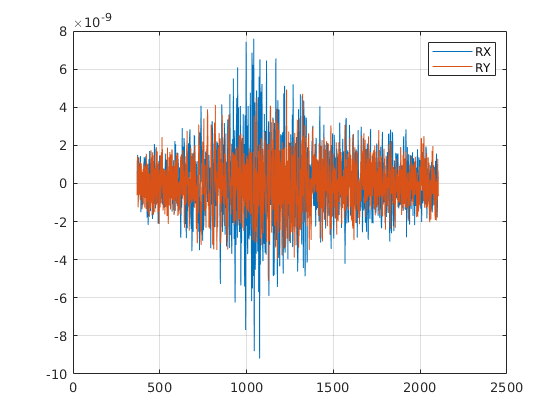

velocityProfileDataLoad;

%% Spectra
avg=9;
[ABRSX, ~] = asd2(BRSX,1/sampF, avg, 1, @hann);
[ABRSY, ~] = asd2(BRSY,1/sampF, avg, 1, @hann);
[ASTSX, ~] = asd2(STSX,1/sampF, avg, 1, @hann);
[ASTSY, ~] = asd2(STSY,1/sampF, avg, 1, @hann);
[ASTSZ, F] = asd2(STSZ,1/sampF, avg, 1, @hann);

[COH,~]=coh2(BRSX,BRSY,1/sampF, avg, 1, @hann);
[COHX,~]=coh2(BRSX,STSZ,1/sampF, avg, 1, @hann);
[COHY,F2]=coh2(BRSY,STSZ,1/sampF, avg, 1, @hann);

[T,~]=tfe2(sqrt(BRSX.^2+BRSY.^2),STSZ,1/sampF, avg, 1, @hann);
[TX,~]=tfe2(BRSX,STSZ,1/sampF, avg, 1, @hann);
[TY,F3]=tfe2(BRSY,STSZ,1/sampF, avg, 1, @hann);

plot(time,BRSY,time,BRSX);
grid on
legend('RX','RY')

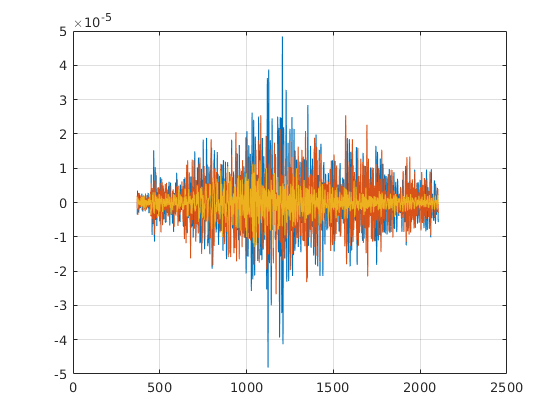


plot(time,STSX,time,STSY,time,STSZ);
grid on

Due to the complex nature of earthquake events, true seismic measurements are far from individual plane waves. However, if we decompose the measured signal into the Fourier domain we get simple equations for the amplitudes at a given frequency:


$$\dot{u_z}=\alpha \omega cos(\zeta)\\
\theta_x=\alpha \kappa cos(\zeta) sin(\psi)\\
\theta_y=\alpha \kappa sin(\zeta) cos(\psi)\\$$


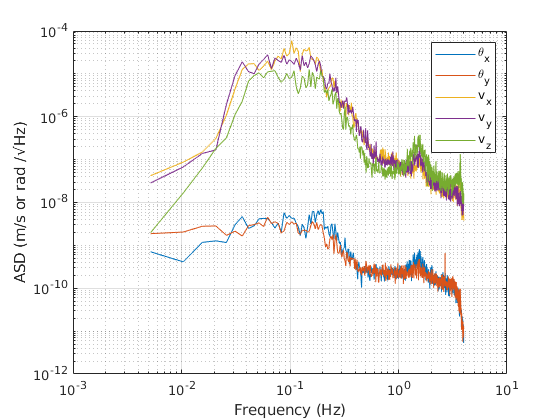

loglog(F,ABRSY,F,ABRSX,F,ASTSX,F,ASTSY,F,ASTSZ);
grid on
ylabel('ASD (m/s or rad /\surd{Hz})')
xlabel('Frequency (Hz)')
legend('\theta_x','\theta_y','v_x','v_y','v_z')

Where the dot represents the time derivative. These can be easily recast into geologically interesting parameters, the Rayleigh wave phase velocity $\nu$ and the angle of incidence $\psi$ of the seismic wave. Here we will only analyze the phase velocity since this encoded the local density profile.


$$\nu\equiv \frac{\omega}{\kappa}=\frac{\dot{u_z}}{\sqrt{\theta_x^2+\theta_y^2}}\\
\psi=arctan\frac{\theta_x}{\theta_y}$$


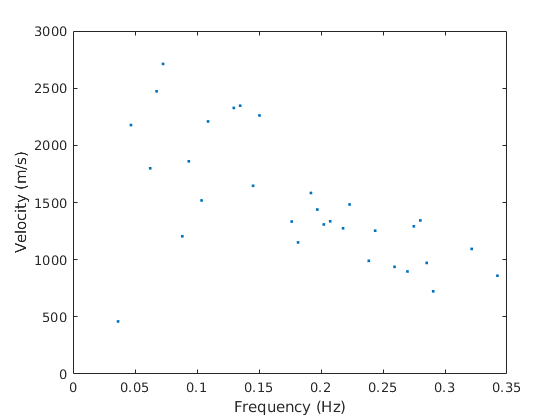

%% Phase Velocity Calculations

thresh=0.8;
Cin=find(and(sqrt(COHX.^2+COHY.^2)>thresh,F2<0.5));
cohV=ASTSZ(Cin)./sqrt(ABRSY(Cin).^2+ABRSX(Cin).^2);
% cohV=abs(real(T(Cin)));
cohF=F(Cin);
vel=[vel; cohV];
vFreq=[vFreq; cohF];

plot(vFreq,vel,'.');
ylabel('Velocity (m/s)')
xlabel('Frequency (Hz)')

## Rayliegh waves to Densities

The Rayliegh wave phase velocity seems like an esoteric quantity to measure. However, it is related to the velocities of the compressional and tranverse wave velocities ($v_l, v_t$) in a fairly straight forward way. In a flat half space the Rayleigh wave velocity ($\nu$) is the solutions of the following equation [2]:


$$(\nu/v_t)^6-8(\nu/v_t)^4+8(\nu/v_t)^2(3-2 (\frac{v_t}{v_l})^2)-16(1-(\frac{v_t}{v_l})^2)=0$$


Luckily this equation only has one real positive root for physical values of $v_l$ and $v_t$. However, the analytical form of this is horrendous and highly non-linear. Additionally, the ground is not a flat half space but a collection of distinct layers which makes the observed Rayleigh wave velocity actually the average over the layers that the wave penetrates to. One clear consequence of this is that the phase velocity is not frequency independent. The measured velocity is determined by the following:


$$\nu=\int_0^\infty \nu(z) A(z) dz$$


Where $z$ is the depth with $z=0$ being the surface of the ground, $\nu(z)$is the the function of Rayleigh wave velocity at a given depth, and $A(z)$ is the attenuation function of the wave which determines the contributions to the average at different depths.

This is clearly going to be difficult to fit with normal methods but we can extract these parameters fairly easily with an optimization algorithm. To do this we choose a given ground model consisting of $n$ layers each with distinct $v_l$, $v_t$, and for every layer except for the last one a depth $d_i$. We then can calculate the dispersion curve for this model and the error between the model curve and the observed curve. We then loop through with some sort of optimization algorithm and then we get a velocity profile.

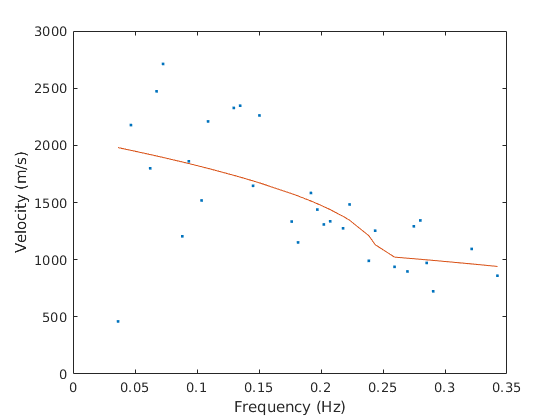

%% Fit
layers=3;
% [bestPar,bestDispers,frames]=dispersionFit(vFreq,vel,layers);
if(layers==3)
    bestDepth=bestPar(1)*heaviside(-(1:5e4)+bestPar(3))+bestPar(4)*heaviside(-(1:5e4)+bestPar(6)).*heaviside((1:5e4)-bestPar(3))+bestPar(7)*heaviside((1:5e4)-bestPar(6));
elseif(layers==2)
    bestDepth=bestPar(1)*heaviside(-(1:5e4)+bestPar(3))+bestPar(4)*heaviside((1:5e4)-bestPar(3));
end

plot(vFreq,vel,'.',vFreq,bestDispers);
ylabel('Velocity (m/s)')
xlabel('Frequency (Hz)')

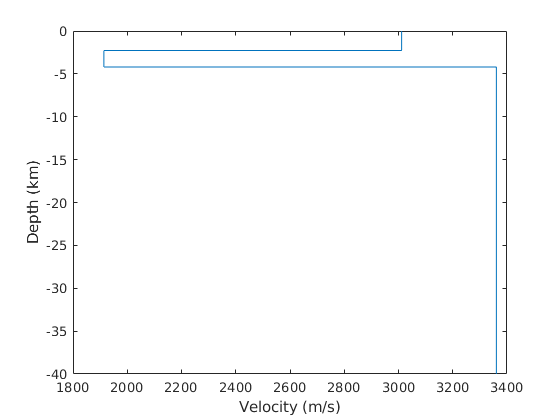


plot(bestDepth,-(1:5e4)/1e3);
xlabel('Velocity (m/s)')
ylabel('Depth (km)')
ylim([-40 0])

This can then be quickly converted into a density profile using the empirical relation [3]:


$$\rho=1.6612 v_l-0.4721 v_l +0.067 v_l^3-0.0043 v_l^4+0.000106 v_l^5$$


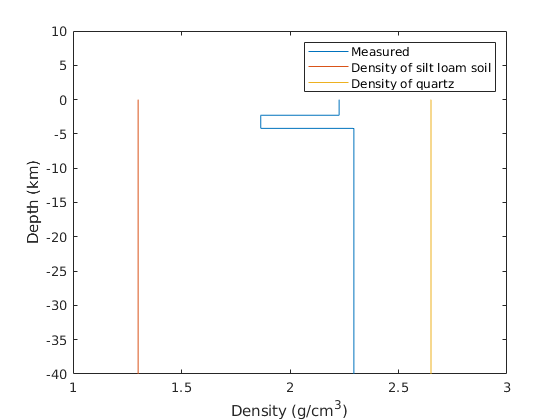

bestDepth=bestDepth/1e3;
dens=1.6612*bestDepth-0.4721*bestDepth.^2+0.0671*bestDepth.^3-0.0043*bestDepth.^4+0.000106*bestDepth.^5;

plot(dens,-(1:5e4)/1e3,1.3+0*(1:5e4),-(1:5e4)/1e3,2.65+0*(1:5e4),-(1:5e4)/1e3);
xlabel('Density (g/cm^3)')
ylabel('Depth (km)')
legend('Measured','Density of silt loam soil','Density of quartz')
xlim([1 3])
ylim([-40 10])

This is then a point like density profile directly below the location of the station. This is compared to the current method of using arrays of seismometers to measure these profiles which intrinsically have some effective area over which they average. With the continued development of roational seismometers one could imagine arrays of such stations giving the ability of three dimensional density profiles with high spatial reslution only limited by the density of the array.

## References:

- Stefano Maranò, Donat Fäh; Processing of translational and rotational motions of surface waves: performance analysis and applications to single sensor and to array measurements, *Geophysical Journal International*, Volume 196, Issue 1, 1 January 2014, Pages 317–339, [https://doi.org/10.1093/gji/ggt187](https://doi.org/10.1093/gji/ggt187)

- Landau, L D; Pitaevskii, L. P.; Kosevich, A. M.; Lifshitz, E.M. (2012). Theory of Elasticity. London: Butterworth-Heinemann.

- Thomas M. Brocher; Empirical Relations between Elastic Wavespeeds and Density in the Earth's Crust. *Bulletin of the Seismological Society of America* ; 95 (6): 2081–2092. doi: [https://doi.org/10.1785/0120050077](https://doi.org/10.1785/0120050077)